Note:Run this code only after running example_Country.mlx or Example_US_cities.mlx

Finding point of Maximum Infection

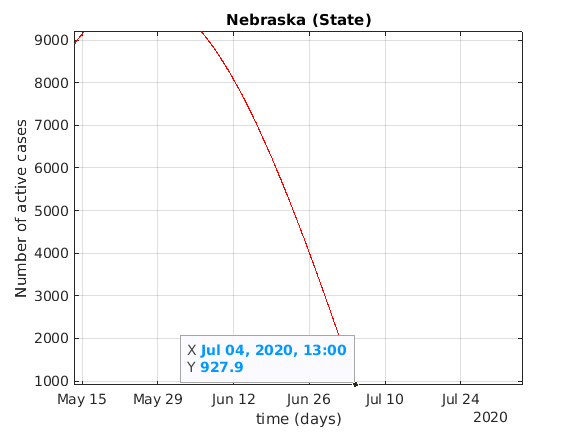

A = Q/delta1-R-D;
A(A<0) = 0;
figure
semilogy(time1,A,'r');

ylim([0,1.1*Npop])
ylabel('Number of active cases')
xlabel('time (days)')

set(gcf,'color','w')
grid on
axis tight
title([Location,' (State)'])
set(gca,'yscale','lin')

[maxI,maxIp] = max(A);
timemaxp = datestr(time1(maxIp));
maxI = floor(maxI);
maxistr = num2str(maxI);
Ans = ['maximum infection at a time was ',maxistr,' on ',timemaxp];
disp(Ans);

maximum infection at a time was 10021 on 26-May-2020 06:00:00


endOfPandemic = find(A==0);
endofP = endOfPandemic(1);
endDate = time1(endofP);
endDate = datestr(endDate)

endDate = '07-Jul-2020 01:00:00'

endDisplay = ['the pendemic will end after ',endDate];
disp(endDisplay);

the pendemic will end after 07-Jul-2020 01:00:00
